# Calibration ToF + Magnitometer

**Magnitometer**

clear; clc;
function [A, b] = calibrateMagnetometer(M)
% CALIBRATEMAGNETOMETER  Fit a 3D ellipsoid to raw magnetometer data (M)
%   and extract the linear transform A and offset b for hard/soft iron
%   correction. 
%
%   Input:
%       M: Nx3 matrix of raw magnetometer readings [Mx, My, Mz].
%          Collect data by rotating the device in many orientations.
%   Output:
%       A: 3x3 soft-iron correction matrix
%       b: 3x1 hard-iron offset
%
%   Usage:
%       [A, b] = calibrateMagnetometer(M);
%       M_corrected = A*(M_raw' - b);
%
%   Reference:
%       This uses a common ellipsoid-fitting approach, solving
%       (M - b)' * inv(C) * (M - b) = 1,
%       then extracting A from inv(C)^(1/2).

    % Ensure data is N-by-3
    if size(M,2) ~= 3
        error('Input M must be Nx3 magnetometer readings.');
    end
    M = double(M);

    % --------------------------------------------------------
    % 1) Build and solve the "ellipsoid fit" matrix equation
    %    We want to fit: (M - b)' * Q * (M - b) = 1
    %    Where Q = A^T A (a positive-definite matrix).
    %    The standard procedure is to expand this to a quadratic form:
    %        X * Beta = 1
    %    Then solve for Beta by least squares.
    % --------------------------------------------------------
    x = M(:,1);  y = M(:,2);  z = M(:,3);

    % Construct the design matrix (9 parameters: center (b), Q upper-tri, etc.)
    % However, the standard approach is often to use 10 parameters for
    % the general quadric, then enforce constraints. Below is a simplified
    % direct ellipsoid fit approach. Various references have slightly different
    % expansions. For clarity, we’ll use a well-known advanced approach from
    % literature with "Ellipsoid" + "Center".
    %
    % We'll use the approach from this reference form:
    %   x'*C*x + D'*x + E = 0
    % but adapted to 1 on the right side. We do a direct library approach here:
    
    % If you want a thoroughly tested solution, you can rely on existing
    % scripts such as "EllipsoidFit" from the MATLAB File Exchange.
    % For brevity, we show a conceptual method below using a smaller set of steps.

    % We'll use a simpler iterative approach: first guess center as the
    % midpoint of min/max, then shift data and do a best-fit on the shape.

    % Initial guess for center:
    b0 = mean(M,1)';  % 3x1

    % Shift data by b0
    M_shifted = M - b0';

    % Now we find the covariance-like matrix for the shifted data
    % to approximate the shape. A simple guess:
    C0 = cov(M_shifted);

    % Or we can refine b0 and C0 iteratively, but let's do one step.

    % Let's finalize b as b0 for a start. If you want a more accurate
    % approach, use a non-linear optimization. For demonstration:
    b = b0;

    % Then let A = inv(sqrtm(C0)), so that (M_shifted) becomes roughly spherical
    [U, S, V] = svd(C0);
    % Make sure S is positive
    if any(diag(S) <= 0)
       error('Data covariance is singular or invalid for ellipsoid fitting.');
    end
    % Compute A from the sqrt of S
    A_approx = U * diag(1./sqrt(diag(S))) * V';
    % This is an approximation to the full "A" that would transform our data to a unit sphere.

    % That’s it for a simple demonstration approach:
    A = A_approx;

    % --------------------------------------------------------
    % In practice, you might do a more thorough least-squares:
    %   1) Nonlinear iteration to refine b
    %   2) Solve for the best A
    %   3) Possibly refine in multiple passes
    % We’re omitting that here for brevity.
    % --------------------------------------------------------

    % Output
    fprintf('[calibrateMagnetometer] Approx. center offset = [%f %f %f]\n', b(1), b(2), b(3));
    fprintf('[calibrateMagnetometer] Approx. A matrix = \n');
    disp(A);

end
rotation = load("trainingData/calib1_rotate.mat");

function [A, b, B_earth, exitflag] = calibrateMagnetometerRefined(Mraw, RmatList, initGuess)
% CALIBRATEMAGNETOMETERREFINED
%   Uses a nonlinear least-squares approach to find magnetometer calibration
%   parameters: A (3x3), b (3x1), and B_earth (3x1) in the global frame,
%   given ground-truth rotation from global->local at each sample and raw
%   magnetometer data in the local frame.
%
%   [A, b, B_earth, exitflag] = calibrateMagnetometerRefined(Mraw, RmatList, initGuess)
%
%   INPUTS:
%       Mraw     : Nx3 matrix of magnetometer readings in robot local frame (distorted).
%       RmatList : 3x3xN array of rotation matrices, where RmatList(:,:,t)
%                  transforms a vector in global->local at time t.
%       initGuess: (optional) struct with fields {A, b, Bearth} to set
%                  initial guesses. If omitted, defaults are used.
%
%   OUTPUTS:
%       A        : 3x3 soft-iron matrix
%       b        : 3x1 hard-iron offset
%       B_earth  : 3x1 Earth magnetic field in the *global* frame
%       exitflag : solver exit condition from lsqnonlin
%
%   MODEL:
%       M_raw(t) = A * ( RmatList(:,:,t)*B_earth + b ),  for t=1..N
%
%   TYPICAL USAGE:
%       1) Convert your ground-truth quaternion to RmatList of size 3x3xN
%       2) Mraw is Nx3 raw magnetometer data
%       3) [A, b, Bg] = calibrateMagnetometerRefined(Mraw, RmatList);
%       4) Then corrected magnetometer reading:
%             M_corr = A^{-1} * Mraw(t) - b
%          or you can do a forward check with your known orientation, etc.
%
%   NOTE: This approach tries to match the entire 3D vector, not just heading.
%         That means pitch/roll variations also help shape the calibration,
%         assuming your ground truth rotation is accurate in 3D.

    % Basic checks
    [N,cols] = size(Mraw);
    if cols ~= 3
        error('Mraw must be Nx3');
    end
    if size(RmatList,1)~=3 || size(RmatList,2)~=3 || size(RmatList,3)~=N
        error('RmatList must be 3x3xN matching Mraw row count.');
    end

    % Default initial guesses
    if nargin < 3, initGuess = struct(); end
    if ~isfield(initGuess,'A'),       initGuess.A      = eye(3); end
    if ~isfield(initGuess,'b'),       initGuess.b      = zeros(3,1); end
    if ~isfield(initGuess,'Bearth'),  initGuess.Bearth = [30e-6; 0; 0]; 
        % e.g. assume ~30 microTesla along X in global frame 
        % (you can refine based on your location on Earth!)
    end

    % Flatten parameters: We'll solve for param = [ b(1..3), A(1..9), B_earth(1..3) ]
    % Total = 3 + 9 + 3 = 15 unknowns
    param0 = packParams(initGuess.A, initGuess.b, initGuess.Bearth);

    % Options for lsqnonlin
    opts = optimoptions('lsqnonlin','Display','iter','MaxFunEvals',1e4,'MaxIter',1e3);

    % Solve
    [paramOpt, ~, ~, exitflag] = lsqnonlin(@(p) costFunc(p, Mraw, RmatList), ...
                                           param0, [], [], opts);

    % Unpack solution
    [A, b, B_earth] = unpackParams(paramOpt);
    
    %--------------------------------------------------
    % Nested local helper: costFunc
    %   Returns residuals for each data sample, stacked in a 3N vector
    %--------------------------------------------------
    function res = costFunc(p, M_local, Rmats)
        [A_, b_, Bg_] = unpackParams(p);
        % For each time t, predict M_raw from the model:
        %   M_pred(t) = A_ * ( R(t)*Bg_ + b_ )
        
        N_ = size(M_local,1);
        res = zeros(3*N_,1);
        idx = 1;
        for t_ = 1:N_
            R_  = Rmats(:,:,t_);
            M_t = M_local(t_,:).';  % Nx3 => column
            M_pred = A_*(R_*Bg_ + b_);
            % residual in 3D
            err3d = M_t - M_pred;
            res(idx:idx+2) = err3d;  % store
            idx = idx+3;
        end
    end

    %--------------------------------------------------
    % Nested: param -> (A, b, B_earth)
    %--------------------------------------------------
    function [A_, b_, Bg_] = unpackParams(p_)
        % p_ = [ b(1..3), A(1..9), Bg_(1..3) ]
        b_  = p_(1:3);
        A_  = reshape(p_(4:12), [3,3]);
        Bg_ = p_(13:15);
    end

    %--------------------------------------------------
    % Nested: (A, b, B_earth) -> param
    %--------------------------------------------------
    function p_ = packParams(A_, b_, Bg_)
        p_ = [ b_; reshape(A_,9,1); Bg_ ];
    end

end

GT_rotation = squeeze(rotation.out.GT_rotation.signals.values);
time = squeeze(rotation.out.GT_time.time);
Mraw = squeeze(rotation.out.Sensor_MAG.signals.values)';

initGuess.A      = eye(3);
initGuess.b      = [0; 0; 0];
initGuess.Bearth = [30e-6; 0; 0];  % or something approximate

% 1) Plot the raw magnetometer readings
figure('Name','Magnetometer and Orientation','Color',[1 1 1]);

subplot(3,1,1);
plot(time, Mraw(:,1), 'r', 'DisplayName','Mx_{raw}'); hold on;
plot(time, Mraw(:,2), 'g', 'DisplayName','My_{raw}');
plot(time, Mraw(:,3), 'b', 'DisplayName','Mz_{raw}');
grid on;  legend('show');
xlabel('Time (s)');
ylabel('Mag (raw)');
title('Raw Magnetometer Readings');

% 2) Convert ground-truth quaternions to Euler angles
%    rotm2eul uses a specific convention. For typical yaw-pitch-roll, pass 'ZYX'.
N = size(GT_rotation,1);
RmatList = zeros(3,3,N);
eulZYX = zeros(N,3); % Each row: [yaw, pitch, roll] in radians
for i = 1:N
    q = GT_rotation(i,:);   % [w x y z]
    R = quat2rotm(q);       % returns 3x3
    % Extract Euler angles (yaw=Z, pitch=Y, roll=X) in radians
    RmatList(:,:,i) = R;
    eulZYX(i,:) = rotm2eul(R, 'ZYX');
end
% Convert to degrees for easier interpretation
yaw   = eulZYX(:,1)*180/pi;
pitch = eulZYX(:,2)*180/pi;
roll  = eulZYX(:,3)*180/pi;
[A, b, B_earth] = calibrateMagnetometerRefined(Mraw, RmatList, initGuess);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0         16       0.000121181                             0.95
     1         32       0.000121181              10             0.95      
     2         48       0.000121181             2.5             0.95      
     3         64       2.74829e-05           0.625            0.296      
     4         80       2.54952e-05            1.25            0.523      
     5         96       7.07041e-06          0.3125            0.198      
     6        112       6.10225e-06           0.625            0.225      
     7        128       5.18554e-06           0.625           0.0868      
     8        144        4.9732e-06           0.625           0.0899      
     9        160       4.96054e-06           0.625           0.0663      
    10        176       4.78818e-06         0.15625           0.0254      



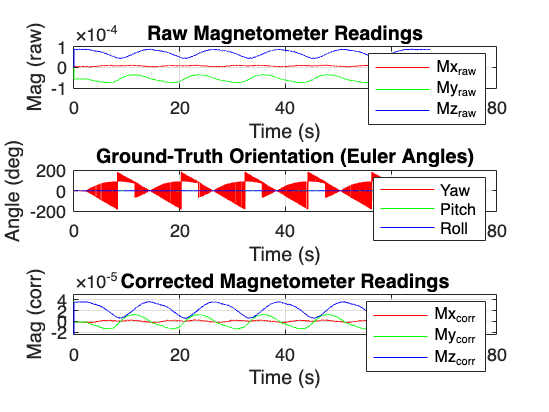



% Plot the ground-truth orientation
subplot(3,1,2);
plot(time, yaw,   '-r', 'DisplayName','Yaw');   hold on;
plot(time, pitch, '-g', 'DisplayName','Pitch');
plot(time, roll,  '-b', 'DisplayName','Roll');
grid on; legend('show');
xlabel('Time (s)');
ylabel('Angle (deg)');
title('Ground-Truth Orientation (Euler Angles)');

% 3) Compute corrected magnetometer readings
%    Model: Mraw = A * (Mideal + b).
%    Then Mideal = A^{-1}*Mraw - b.

A_inv = inv(A);
N = size(Mraw,1);
M_corr = zeros(N,3);
for i = 1:N
    rawVec       = Mraw(i,:).';               % 3x1
    correctedVec = A_inv * rawVec - b;        % 3x1
    M_corr(i,:)  = correctedVec.';
end

% Plot corrected magnetometer readings
subplot(3,1,3);
plot(time, M_corr(:,1), 'r', 'DisplayName','Mx_{corr}'); hold on;
plot(time, M_corr(:,2), 'g', 'DisplayName','My_{corr}');
plot(time, M_corr(:,3), 'b', 'DisplayName','Mz_{corr}');
grid on; legend('show');
xlabel('Time (s)');
ylabel('Mag (corr)');
title('Corrected Magnetometer Readings');

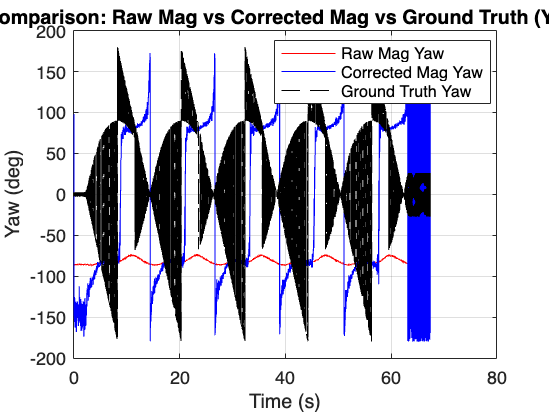

% 1) Compute yaw from raw magnetometer
%    heading_raw(t) = atan2(My_raw, Mx_raw)
heading_raw_rad = atan2(Mraw(:,2), Mraw(:,1));
heading_raw_deg = heading_raw_rad * (180/pi);

% 2) Compute yaw from corrected magnetometer
heading_corr_rad = atan2(M_corr(:,2), M_corr(:,1));
heading_corr_deg = heading_corr_rad * (180/pi);

% 3) Compute yaw from ground truth quaternions
N = size(GT_rotation,1);
yawGT_deg = zeros(N,1);

for i = 1:N
    q = GT_rotation(i,:);     % [w, x, y, z]
    R = quat2rotm(q);         % 3x3
    % Extract Euler angles with 'ZYX' => [yaw, pitch, roll]
    eulZYX = rotm2eul(R,'ZYX');
    yawGT_deg(i) = eulZYX(1)*180/pi;  % yaw in degrees
end

% Optionally, we can unwrap or keep it wrapped in [-180,180].
% e.g. yawGT_deg = unwrap(yawGT_deg*pi/180)*180/pi;

% 4) Plot all three angles vs. time
figure('Color','w','Name','Heading Comparison');

plot(time, heading_raw_deg,  'r-', 'DisplayName','Raw Mag Yaw'); hold on;
plot(time, heading_corr_deg, 'b-', 'DisplayName','Corrected Mag Yaw');
plot(time, yawGT_deg,        'k--','DisplayName','Ground Truth Yaw');
grid on; xlabel('Time (s)'); ylabel('Yaw (deg)');
legend('Location','best');
title('Comparison: Raw Mag vs Corrected Mag vs Ground Truth (Yaw)');

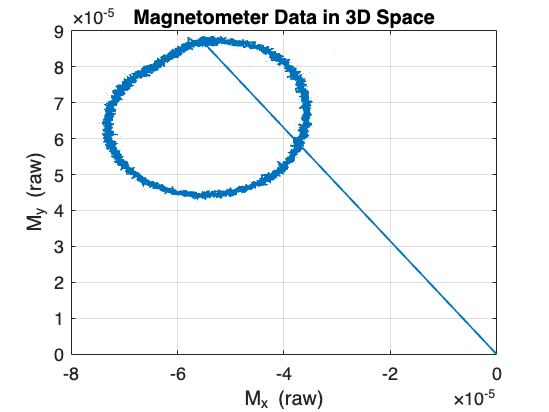


figure('Name','3D Magnetometer Plot','Color',[1 1 1]);
plot(Mraw(:,2), Mraw(:,3), 'LineWidth', 1.0);
grid on;
xlabel('M_x (raw)');
ylabel('M_y (raw)');
% zlabel('M_z (raw)');
title('Magnetometer Data in 3D Space');